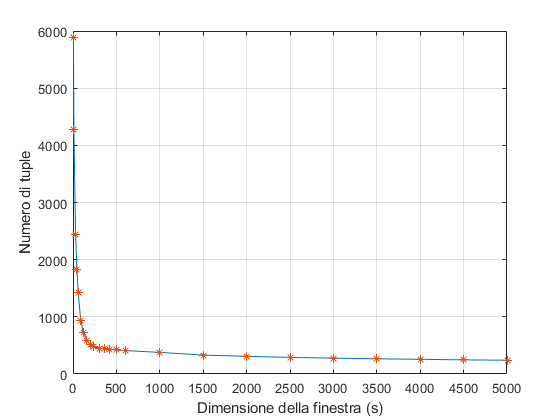

%Mercury
CWIN = [5, 10, 30, 45, 60, 90, 120, 160, 200, 240, 300, 360, 420, 500, 600, 1000, 1500, 2000, 2500, 3000, 3500, 4000, 4500, 5000];
n_tuple_mercury = [5880,4283,2436,1835,1428,928,725,594,508,476,453,440,430,421,410,378,331,310,290,278,266,257,247,241];
plot(CWIN,n_tuple_mercury,CWIN,n_tuple_mercury,'*')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%360
saveas(gcf,'tupleCountMercury','png');

clf

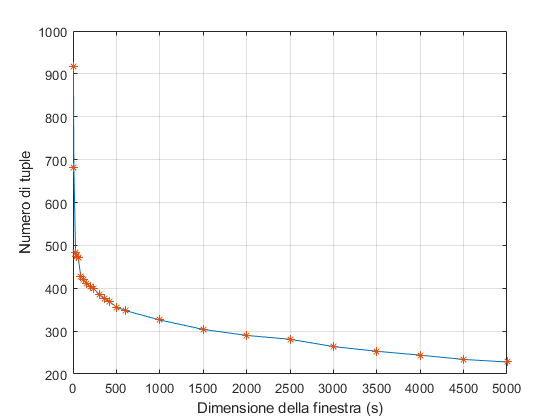

clear

%bgl 
n_tuple_bgl=[918,681,484,474,471,428,421,410,403,399,385,375,369,356,348,326,304,290,281,264,253,244,234,228];
CWIN = [5, 10, 30, 45, 60, 90, 120, 160, 200, 240, 300, 360, 420, 500, 600, 1000, 1500, 2000, 2500, 3000, 3500, 4000, 4500, 5000];
plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'*')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%420
saveas(gcf,'tupleCountBLG','png');

clf

%mercury
clear
id = fopen("C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\5\design\ffdatoolsetIE2016\tupling_MercuryErrorLog-360\interarrivals.txt");
intarrivals = fscanf(id,'%d');
[p,t]=cdfcalc(intarrivals);
ttf=p(2:size(p,1));
rel = 1-ttf;

subplot(2,2,1)
plot(t,ttf,'--',t,rel,':r','LineWidth',2);
xlabel('Tempo (s)')
ylabel('p')
grid on
title('CDF Empirica');

%Esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.352131586294421 -2.22768270295095e-05];
% Fit model to data.
[f1, ~] = fit( xData, yData, ft, opts )

f1 =      General model Exp1:
     f1(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.9011  (0.891, 0.9112)
       b =  -8.484e-05  (-8.746e-05, -8.221e-05)

model=feval(f1,t);
[~,~,~] = kstest2(rel,model)

%plot Esponenziale
subplot(2,2,2);
h = plot( f1, xData, yData );
legend( h, 'rel vs. t', 'Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Esponenziale')

%Iper_esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1.29618063668875 -2.81249338835857e-05 -0.691281124730794 -2.10979088537547e-05];
% Fit model to data.
% Fit model to data.
[f1, ~] = fit( xData, yData, ft, opts )

f1 =      General model Exp2:
     f1(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =      0.4125  (0.3978, 0.4272)
       b =  -0.0008358  (-0.0008995, -0.0007721)
       c =      0.7091  (0.6976, 0.7205)
       d =  -5.883e-05  (-6.032e-05, -5.735e-05)

model=feval(f1,t);
[~,~,~] = kstest2(rel,model)

% Plot Iper-esponenziale
subplot(2,2,3)
h = plot( f1, xData, yData );
legend( h, 'rel vs. t', 'Iper-Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Iper-esponenziale')

%Weibull
%Calcolo di 1 / mean(TTF)
sum=0;
for i=1:length(ttf)
    sum=sum+ttf(i);
end
ttf_mean=sum/length(ttf);
l=1/ttf_mean;

[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp(-(l*x)^a)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.5 0.00001];
% Fit model to data.
[f1, ~] = fit( xData, yData, ft, opts )

f1 =      General model:
     f1(x) = exp(-(l*x)^a)
     Coefficients (with 95% confidence bounds):
       a =      0.7066  (0.6952, 0.718)
       l =   9.427e-05  (9.274e-05, 9.581e-05)

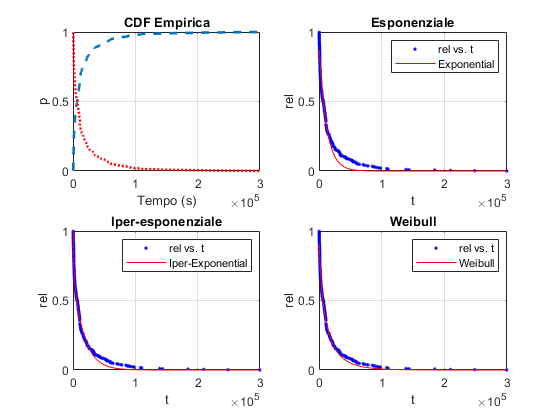

model=feval(f1,t);
[~,~,~] = kstest2(rel,model)

% Plot Weibull
subplot(2,2,4)
h = plot( f1, xData, yData );
legend( h, 'rel vs. t', 'Weibull', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Weibull')
saveas(gcf,'ReliabilityEs1mercury','png')

clf

clear
id = fopen("C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\5\design\ffdatoolsetIE2016\tupling_BGLErrorLog-420\interarrivals.txt");
intarrivals = fscanf(id,'%d');
[p,t]=cdfcalc(intarrivals);
ttf=p(2:size(p,1));
rel = 1-ttf;

subplot(2,2,1)
plot(t,ttf,'--',t,rel,':r','LineWidth',2);
xlabel('Tempo (s)')
ylabel('p')
grid on
title('CDF Empirica');

%Esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.352131586294421 -2.22768270295095e-05];
% Fit model to data.
[f1, ~] = fit( xData, yData, ft, opts )

f1 =      General model Exp1:
     f1(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.8822  (0.8716, 0.8928)
       b =   -5.38e-05  (-5.561e-05, -5.2e-05)

model=feval(f1,t);
[~,~,~] = kstest2(rel,model)

%plot Esponenziale
subplot(2,2,2);
h = plot( f1, xData, yData );
legend( h, 'rel vs. t', 'Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Esponenziale')

%Iper_esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1.29618063668875 -2.81249338835857e-05 -0.691281124730794 -2.10979088537547e-05];
% Fit model to data.
[f1, ~] = fit( xData, yData, ft, opts )

f1 =      General model Exp2:
     f1(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =      0.3799  (0.3735, 0.3862)
       b =  -0.0003572  (-0.0003701, -0.0003443)
       c =      0.6468  (0.6399, 0.6536)
       d =  -3.442e-05  (-3.492e-05, -3.393e-05)

model=feval(f1,t);
[~,~,~] = kstest2(rel,model)

% Plot Iper-esponenziale
subplot(2,2,3)
h = plot( f1, xData, yData );
legend( h, 'rel vs. t', 'Iper-Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Iper-esponenziale')

%Weibull
%Calcolo di 1 / mean(TTF)
sum=0;
for i=1:length(ttf)
    sum=sum+ttf(i);
end
ttf_mean=sum/length(ttf);
l=1/ttf_mean;

[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp(-(l*x)^a)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.5 0.00001];
% Fit model to data.
[f1, ~] = fit( xData, yData, ft, opts )

f1 =      General model:
     f1(x) = exp(-(l*x)^a)
     Coefficients (with 95% confidence bounds):
       a =      0.6773  (0.6693, 0.6854)
       l =   6.279e-05  (6.202e-05, 6.356e-05)

model=feval(f1,t);
[H,P,K] = kstest2(rel,model)

H = logical
   0


P = 0.2224

K = 0.0769

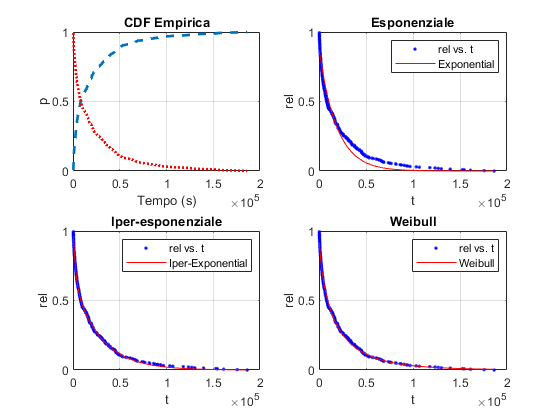


% Plot Weibull
subplot(2,2,4)
h = plot( f1, xData, yData );
legend( h, 'rel vs. t', 'Weibull', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Weibull')
saveas(gcf,'ReliabilityEs1bgl','png')

clf